clearvars -except eCNN APEsCNN eANN APEsANN ANNdt eARIMA APEsARIMA ARIMAdt eMLR APEsMLR   

% eCNN = eRLS; AEsCNN = rls_AEs; APEsCNN = rls_APEs; CNNdt = testsetdt; %CNN
% eANN = eRLS; AEsANN = rls_AEs; APEsANN = rls_APEs; ANNdt = time_outputs; %ANNSTLF
% eARIMA = errors; AEsARIMA = AEs; APEsARIMA = APEs; ARIMAdt = testd.DateTime; %ARIMA
% eMLR = errors; AEsMLR = AEs; APEsMLR = APEs; MLRdt = testd.DateTime; %MLR
% eSNF = errors; AEsSNF = AEs; APEsSNF = APEs; SNFdt = testd.DateTime; %SNF

## Hourly Horizon Analysis

CANNdt = ANNdt;    % DateTime of the test dataset
Othersdt = ARIMAdt;

figure;
CANNtime24 = CANNdt.Hour + 1; % Time = 1...24 hrs
Otherstime24 = Othersdt.Hour + 1;

clear t
t = tiledlayout(2,4);
t.Padding = 'tight';     % uses all the spaces in the figure window
t.TileSpacing = 'tight';
clear sgtitle
sgt = sgtitle("Hourly Horizon - Toronto Dataset - Errors, AEs, APEs");
sgt.FontSize = 20;
warning('off', 'MATLAB:handle_graphics:Layout:NoPositionSetInTiledChartLayout');


### Box Plots

% CNN
sp(1) = nexttile(1);
boxplot(eCNN, CANNtime24)
title('Convolutional Neural Network (RLS)')

% ANN
sp(2) = nexttile(2);
boxplot(eANN, CANNtime24)
title('Artificial Neural Network (RLS)')

% MLR
sp(3) = nexttile(3);
boxplot(eMLR, Otherstime24)
title('Multiple Linear Regression (MLR)')

% ARIMA
sp(4) = nexttile(4);
boxplot(eARIMA, Otherstime24)
title('ARIMA')

linkaxes(sp, 'y')
clear sp

### Absolute Percent Errors plot

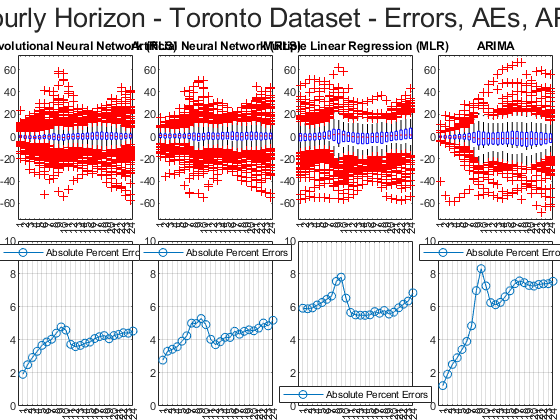

APEsCNN = APEsCNN(:);
APEsLSTM = APEsLSTM(:);
APEsANN = APEsANN(:);
APEsARIMA = APEsARIMA(:);
APEsMLR = APEsMLR(:);

% CNN
sp(1) = nexttile(5);
stats = grpstats(APEsCNN, CANNdt.Hour, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:24)
legend('Absolute Percent Errors', 'Location','best')
grid on

% ANN
sp(2) = nexttile(6);
stats = grpstats(APEsANN, CANNdt.Hour, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:24)
legend('Absolute Percent Errors', 'Location','best')
grid on

% MLR
sp(3) = nexttile(7);
stats = grpstats(APEsMLR, Othersdt.Hour, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:24)
legend('Absolute Percent Errors', 'Location','best')
grid on

% ARIMA
sp(4) = nexttile(8);
stats = grpstats(APEsARIMA, Othersdt.Hour, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:24)
legend('Absolute Percent Errors', 'Location','best')
grid on

linkaxes(sp, 'y')

## Daily Horizon

figure;
[dnumCANN, dnameCANN] = weekday(CANNdt, 'long');
[dnumOthers, dnameOthers] = weekday(Othersdt, 'long');
labeld = {'Monday', 'Tuesday', 'Wednesday', 'Thursday', 'Friday', 'Saturday', 'Sunday'};

t = tiledlayout(2,4);
t.Padding = 'tight';     % uses all the spaces in the figure window
t.TileSpacing = 'tight';
sgt = sgtitle("Daily Horizon - Toronto Dataset - Errors, AEs, APEs");
sgt.FontSize = 20;
warning('off', 'MATLAB:handle_graphics:Layout:NoPositionSetInTiledChartLayout');

### Box Plots

xtick = [7,1,2,3,4,5,6];    % the position we want them displayed as, i.e Mon - Sun

% CNN
sp(1) = nexttile(1);
boxplot(eCNN, dnumCANN,'positions', xtick)
set(gca, 'XTickLabel', labeld)
title('Convolutional Neural Network (RLS)')

% ANN
sp(2) = nexttile(2);
boxplot(eANN, dnumCANN,'positions', xtick)
set(gca, 'XTickLabel', labeld)
title('Artificial Neural Network (RLS)')

% MLR
sp(3) = nexttile(3);
boxplot(eMLR, dnumOthers,'positions', xtick)
set(gca, 'XTickLabel', labeld)
title('Multiple Linear Regression (MLR)')

% ARIMA
sp(4) = nexttile(4);
boxplot(eARIMA, dnumOthers,'positions', xtick)
set(gca, 'XTickLabel', labeld)
title('ARIMA')

linkaxes(sp, 'y')
clear sp

### Absolute Percent Errors plot

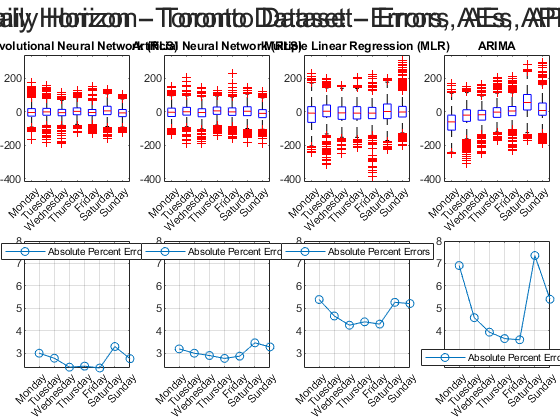

% APEsCNN = APEsCNN(:);
% APEsANN = APEsANN(:);
% APEsARIMA = APEsARIMA(:);
% APEsMLR = APEsMLR(:);

% CNN
sp(1) = nexttile(5);
stats = grpstats(APEsCNN, dnumCANN, "mean");
stats = [stats(2:7); stats(1)];     % aligns for Mon - Sun
plot(stats, '-o')
set(gca,'XTick',1:1:7)
set(gca, "XTickLabel", labeld)
legend('Absolute Percent Errors', 'Location','best')
grid on

% ANN
sp(2) = nexttile(6);
stats = grpstats(APEsANN, dnumCANN, "mean");
stats = [stats(2:7); stats(1)];     % aligns for Mon - Sun
plot(stats, '-o')
set(gca,'XTick',1:1:7)
set(gca, "XTickLabel", labeld)
legend('Absolute Percent Errors', 'Location','best')
grid on

% MLR
sp(3) = nexttile(7);
stats = grpstats(APEsMLR, dnumOthers, "mean");
stats = [stats(2:7); stats(1)];     % aligns for Mon - Sun
plot(stats, '-o')
set(gca,'XTick',1:1:7)
set(gca, "XTickLabel", labeld)
legend('Absolute Percent Errors', 'Location','best')
grid on

% ARIMA
sp(4) = nexttile(8);
stats = grpstats(APEsARIMA, dnumOthers, "mean");
stats = [stats(2:7); stats(1)];     % aligns for Mon - Sun
plot(stats, '-o')
set(gca,'XTick',1:1:7)
set(gca, "XTickLabel", labeld)
legend('Absolute Percent Errors', 'Location','best')
grid on

linkaxes(sp, 'y')

## Monthly Horizon

figure;
labelm = {'Jan', 'Feb', 'Mar', 'Apr', 'May', 'Jun', 'Jul', 'Aug',...
          'Sep', 'Oct', 'Nov', 'Dec'};

t = tiledlayout(2,4);
t.Padding = 'tight';     % uses all the spaces in the figure window
t.TileSpacing = 'tight';

sgt = sgtitle("Monthly Horizon - Toronto Dataset - Errors, AEs, APEs");
sgt.FontSize = 20;
warning('off', 'MATLAB:handle_graphics:Layout:NoPositionSetInTiledChartLayout');

### Box Plots

% CNN
sp(1) = nexttile(1);
boxplot(eCNN, CANNdt.Month,'labels', labelm)
title('Convolutional Neural Network (RLS)')

% ANN
sp(2) = nexttile(2);
boxplot(eANN, CANNdt.Month,'labels', labelm)
title('Artificial Neural Network (RLS)')

% MLR
sp(3) = nexttile(3);
boxplot(eMLR, Othersdt.Month,'labels', labelm)
title('Multiple Linear Regression (MLR)')

% ARIMA
sp(4) = nexttile(4);
boxplot(eARIMA, Othersdt.Month,'labels', labelm)
title('ARIMA')

linkaxes(sp, 'y')
clear sp

### Absolute Percent Errors plot

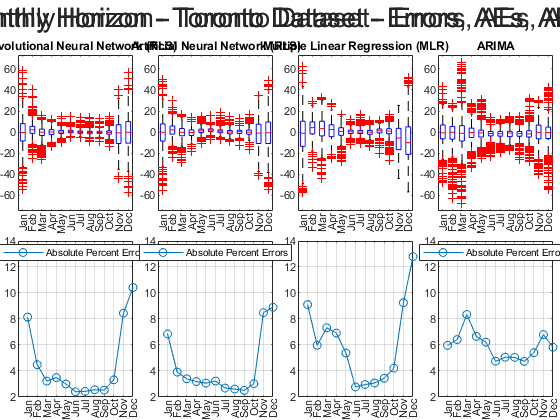

APEsCNN = APEsCNN(:);
APEsANN = APEsANN(:);
APEsARIMA = APEsARIMA(:);
APEsMLR = APEsMLR(:);

% CNN
sp(1) = nexttile(5);
stats = grpstats(APEsCNN, CANNdt.Month, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:12)
set(gca,'XTickLabel', labelm)
legend('Absolute Percent Errors', 'Location','best')
grid on

% ANN
sp(2) = nexttile(6);
stats = grpstats(APEsANN, CANNdt.Month, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:12)
set(gca,'XTickLabel', labelm)
legend('Absolute Percent Errors', 'Location','best')
grid on

% MLR
sp(3) = nexttile(7);
stats = grpstats(APEsMLR, Othersdt.Month, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:12)
set(gca,'XTickLabel', labelm)
% legend('Absolute Errors / 100','Absolute Percent Errors', 'Location','northwest')
grid on

% ARIMA
sp(4) = nexttile(8);
stats = grpstats(APEsARIMA, Othersdt.Month, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:12)
set(gca,'XTickLabel', labelm)
legend('Absolute Percent Errors', 'Location','best')
grid on

linkaxes(sp, 'y')